clear;
x = [0, 1]

x =      0     1


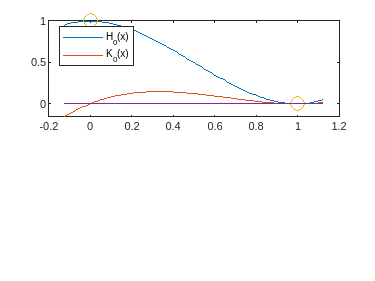

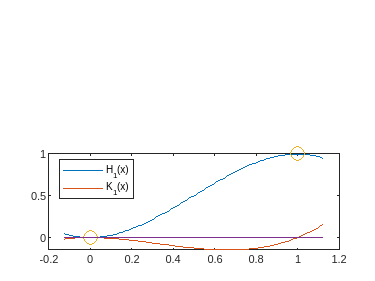

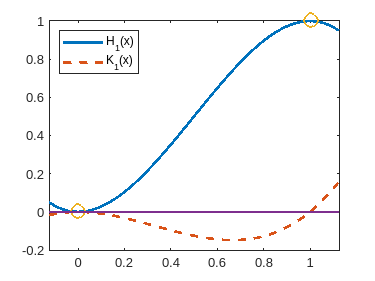

y = sin(x*pi/4);
z = pi/4*cos(x*pi/4);

n = length(x);

X=x(1)-0.125:1e-2:x(end)+.125;


I=eye(n);
for i=1:n
   L = polyfit(x, I(i,:), n-1);  dL = polyder(L);
   l(i,:) = polyval(L, X);     dl(i,:) = polyval(dL, X);
   H(i,:) = (l(i,:).^2).*(1 - 2*dl(i,:).*(X - x(i)));
   K(i,:) = (l(i,:).^2).*(X - x(i));

   figure(1);
   subplot(n,1,i);
   plot(X,H(i,:),X,K(i,:),x,I(i,:),'o',X,X*0,'MarkerSize',10);
   Hl = sprintf('H_%d(x)', i-1);
   Kl = sprintf('K_%d(x)', i-1);

   legend(Hl, Kl,'Location','northwest');


   figure(10+i);
   plot(X, H(i,:), X, K(i,:), '--', x,I(i,:),'o', ...
      X,X*0, ...
      'MarkerSize',10, ...
      'LineWidth', 2);
   legend(Hl, Kl,'Location','northwest');

   %       axis([x(1)-0.2 x(end)+.2 -0.3 1.2])
end

Plot H's

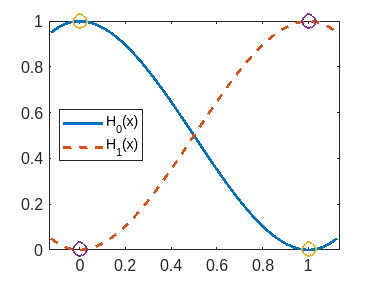

figure(20);
plot(X, H(1,:), X, H(2,:), '--', ...
   x,I(1,:),'o', x,I(2,:),'o', ...
   'MarkerSize',10, 'LineWidth', 2);
legend('H_0(x)', 'H_1(x)','Location','west');
set(gca, 'FontSize', 12);
axis equal

Plots K's

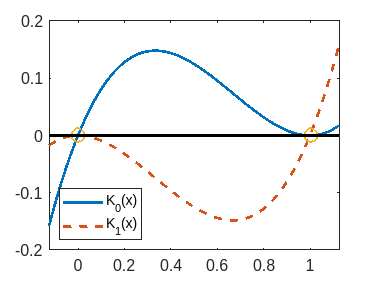

figure(21);
plot(X, K(1,:), X, K(2,:), '--', x,[0,0],'o', ...
   X,X*0, 'k-', 'MarkerSize',10, 'LineWidth', 2);
legend('K_0(x)', 'K_1(x)','Location','southwest');
set(gca, 'FontSize', 12);